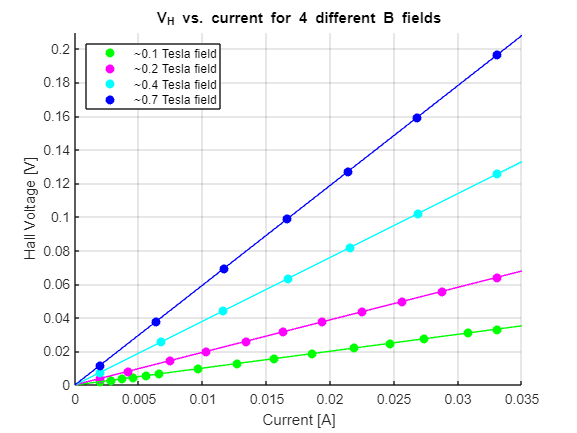

%clearing crap
clear all 
clf

%declaring symbolic variables
syms x

%declaring straight lines
t01(x) = 1.005672*x + 1.108322E-5;
t02(x) = 1.935402*x + 1.066967E-4;
t04(x) = 3.795196*x + 3.110003E-5;
t07(x) = 5.939717*x + 7.386115E-5;

%importing data for points
t01d = importdata("01tesla.txt");
t02d = importdata("02tesla.txt");
t04d = importdata("04tesla.txt");
t07d = importdata("07tesla.txt");

%plotting points
plot(t01d(:,1),t01d(:,2),"go","MarkerFaceColor","g")
hold on
plot(t02d(:,1),t02d(:,2),"mo","MarkerFaceColor","m")
hold on
plot(t04d(:,1),t04d(:,2),"co","MarkerFaceColor","c")
hold on
plot(t07d(:,1),t07d(:,2),"bo","MarkerFaceColor","b")
hold on

%plotting lines
fplot(t01, "g-")
hold on
fplot(t02, "m-")
hold on
fplot(t04, "c-")
hold on
fplot(t07, "b-")
hold off

%setting sensible limits
xlim([0 0.035])
ylim([0 0.21])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

%labelling graph
xlabel("Current [A]");
ylabel("Hall Voltage [V]");
title("V_{H} vs. current for 4 different B fields")
legend("~0.1 Tesla field","~0.2 Tesla field","~0.4 Tesla field","~0.7 Tesla field","Location","NorthWest")

clear all 
clf

%declaring values
Nc = 1E25;
Nv = 6E24;
Eg = 1.0574365844E-19;
T = 293.65;
kb = 1.380649E-23;

%calculating number of charge carriers
n = sqrt(Nv*Nc)*exp(-Eg/(2*kb*T))

n =       1.68050298257821e+19



format longg
B=0.1010108;
m=1.005672;
e=1.6021766E-19;
d=0.001068;

n2 = B/(m*e*d)

n2 =       5.86988800085477e+20
